%EE354 MIDTERM
%Lisa Jacklin
%10/20/2022

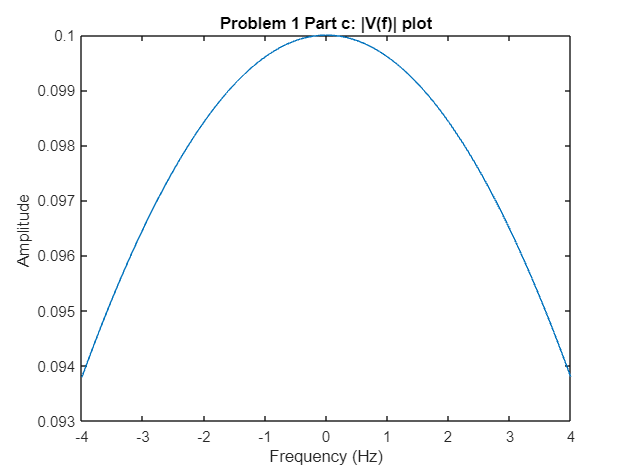

%Problem 1 
% Part c

A1 = 1;A2 = 2;
T1 = 2; T2 = 1; %s
tau = 1;

time = -T1:tau:T1; %this should give the time range required
l = length(time);
%generate v(n) as a rectangular pulse
for n = 1:l
    if abs(time(n)) <= T2
       v(n) = A2;
    end

    if abs(time (n)) > T1
        v(n) = A1;
    end

    if abs(time(n)) > T1
        v(n) = 0;
    end 
end 

fs = 100; ts = 1/fs; 
%generate frequency domain..
N = 2^16;
df = fs/N;
f = -(fs/2 - df) : df : fs/2;
Vf = ts*fftshift(fft(v, N));
%frequency range is -4 to 4 Hz with 0.01 Hz increments

plot(f, abs(Vf));
    title("Problem 1 Part c: |V(f)| plot")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude ")
    xlim([-4, 4]); %displays only this frequency range

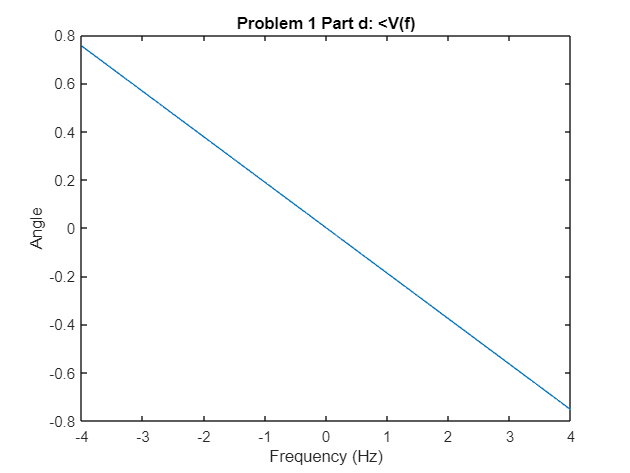


%Problem 1
%Part d

%plotting the angle of V(f) over the same range

plot (f, angle(Vf))
    title("Problem 1 Part d: <V(f)")
    xlabel("Frequency (Hz)")
    ylabel("Angle")
     xlim([-4, 4]);

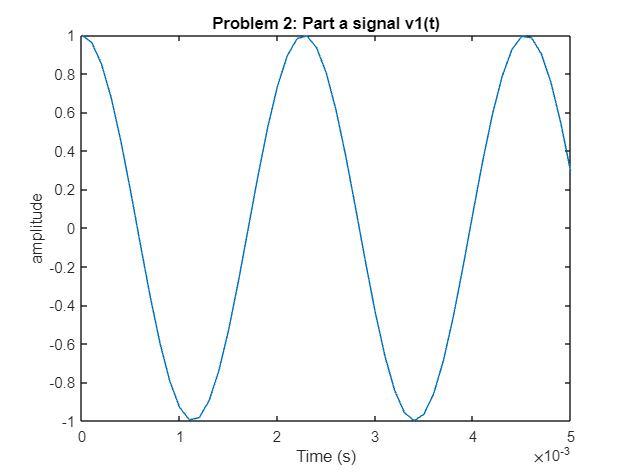

%Problem 2
%Part a

fs = 10000; ts = 1/fs;
T1 = 1; T2 = 10; %second duration
time1 = 0:ts:T1;

v1 = cos(2*pi*440.50 *time1);
plot (time1, v1)
    title("Problem 2: Part a signal v1(t)")
    xlabel("Time (s)")
    ylabel("amplitude")
    xlim ([0 0.005]) %this should make it easier to view the signal v1(t)

    %the condensed signal v1(t) is due to the sampling frequency and thus
    %the sampling time. This graph has been zoomed in for better viewing.


    %Part B
    V1f = ts*fftshift(fft(v1, M));
       M = 2^16; %set value given by problem
       df = fs/M;
        freq = -(fs/2 - df) : df : fs/2;

    plot (freq, V1f)

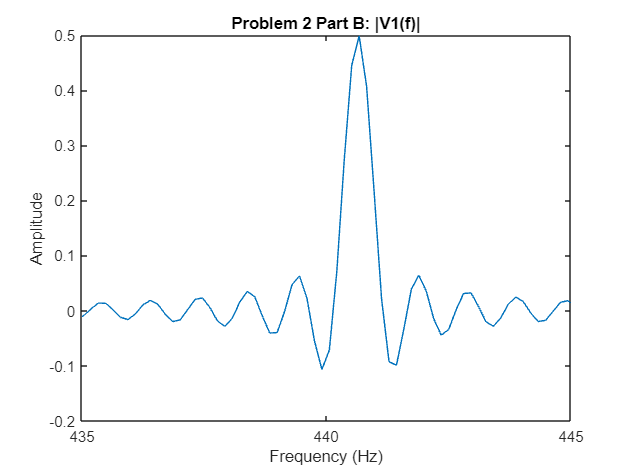

        title ("Problem 2 Part B: |V1(f)|")
        xlabel("Frequency (Hz)")
        xlim ([435 445]) %limits given by problem
        ylabel("Amplitude")

Part C: Do you think based on inspection, that sample 1 is adequate to identify and measure the fundamental frequencies of each of the two violins? What is the frequency resolution in this case?

- Based on inspection, I thing sample 1 is adequate to identify and measure the fundamental frequencies of each of the violins because the frequency is low enough, that from simply looking at the graph displayed above, we can make a pretty go estimate of what the fundamental frequency is to be around.

- In this case, the frequency resolution is 10,000/10 so 1000Hz.

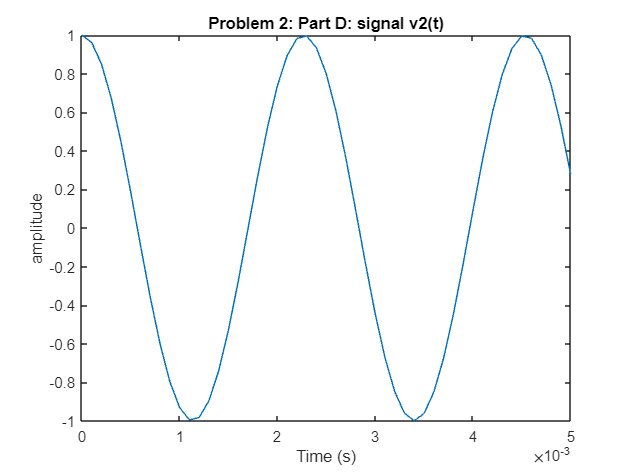


%part D
%remember, T2 is 10s.
time2 = 0:ts:T2;
v2 = cos(2*pi*441.00*time2);



plot (time2, v2)
    title("Problem 2: Part D: signal v2(t)")
    xlabel("Time (s)")
    ylabel("amplitude")
    xlim ([0 0.005]) %this should make it easier to view the signal v1(t)


%Part E
N = 2^18;
df2 = fs/N;
freq2 = -(fs/2 - df2) : df2 : fs/2;

V2f = ts*fftshift(fft(v2, N)); 
     plot (freq2, V2f)

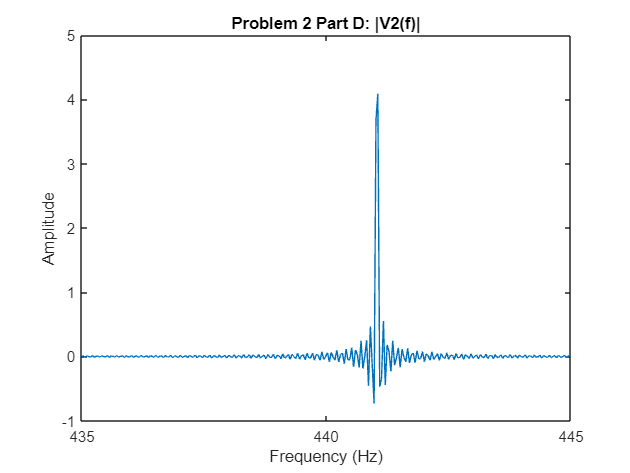

        title ("Problem 2 Part D: |V2(f)|")
        xlabel("Frequency (Hz)")
        xlim ([435 445]) %limits given by problem
        ylabel("Amplitude")

Part F: Do you think that sample 2 is adequate to identify and measure the fundamental frequencies of each of the two violins? 

What is the frequency resolution in this case?

- I think that sample two would prove a challenge to identify and measure the fundamental frequency of the two violins so I would prefer going with the first sample rather than the second sample to make any measurements.

- In this case, the frequency resolution is again 1000Hz.

Part G: What is the general relation between the two frequencies, f1 and f2, that you want to resolve and the minimum length (s)

of sample that you must use to determine the spectrum?

- the general relation between the frequencies is that they have different amplitudes, and periods for each, thus a change in pitch between the two frequencies being measured.

- The minimum number of samples that should be used to determine the spectrum is 100.

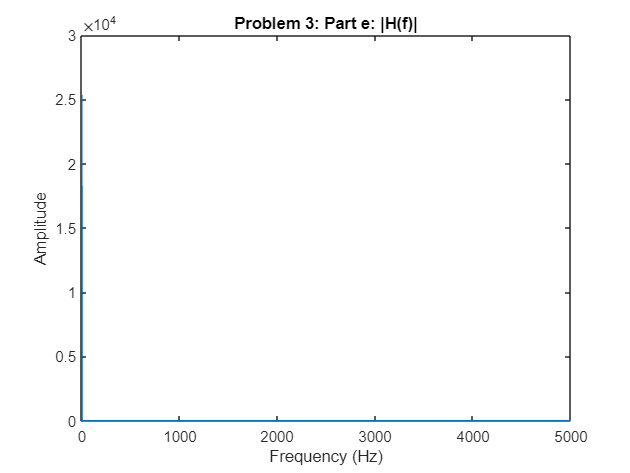

%Problem 3
%part e

%frequency range is 0 to 5000
% use step size 1
L = 39.47; R = 4442.8; C = 1e-6;
a = [1 L/R L*C];
b = [1];

f = 0:1:5000; %frequency range
w =2*pi*f; %radians
%frequency domain equation
H = freqs(b,a,w);

plot (f, abs(H))
    title("Problem 3: Part e: |H(f)|")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude")

 %part f
 %magnitude of |H(f)| when the frequency is
 % f= 0 ,H(f) = 0.9998
 hf1 = 1/(1+2*pi*0*L/R+2*pi*L*C);
 disp (hf1);

    0.9998




 %f = B/2 (500Hz), H(f) = 0.0346
 hf2 = 1/(1+2*pi*500*L/R+2*pi*L*C);
 disp (hf2);

    0.0346





 %f = 3B (3000 Hz), H(f) = 0.0059
 hf3 = 1/(1+2*pi*3000*L/R+2*pi*L*C);
 disp (hf3);

    0.0059



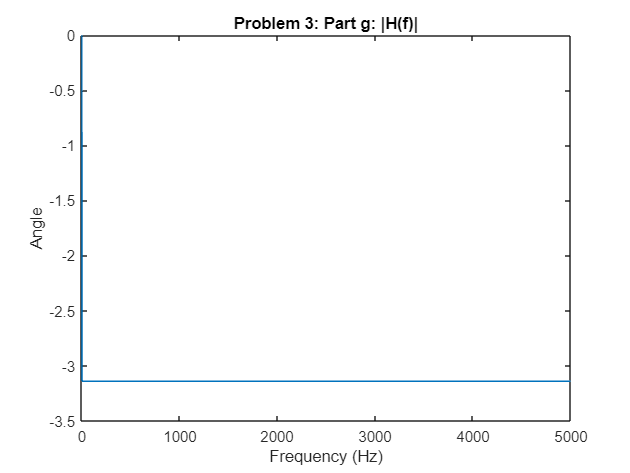


%part g
plot (f, angle(H))
    title("Problem 3: Part g: |H(f)|")
    xlabel("Frequency (Hz)")
    ylabel("Angle")



 %part h
 %angle of |H(f)| when the frequency is
 % f= 0, <H(f) = 0
 hf = 1/(1+2*pi*0*L/R+2*pi*L*C);
 disp (angle(hf));

     0



 %f = B/2 (500Hz)<H(f) =0
  hf5 = 1/(1+2*pi*500*L/R+2*pi*L*C);
 disp (angle(hf5));

     0



 %f = B (1000 Hz), <H(f) =0
  hf1 = 1/(1+2*pi*1000*L/R+2*pi*L*C);
 disp (angle(hf1));

     0



 %f = 2B (2000Hz), < H(f) = 0
    hf2 = 1/(1+2*pi*2000*L/R+2*pi*L*C);
 disp (angle(hf2));

     0



 %f = 3B (3000 Hz), <H(f) = 0
 hf3 = 1/(1+2*pi*3000*L/R+2*pi*L*C);
 disp (angle(hf3));

     0



 Part I: is the response approximately linear over the passband (b) of the filter?

- The response here should be linear over the passband of the filter since the passband that was given is 1000Hz but the frequency range that we are asked to cover is 5000Hz.What is currently displayed is not linear through the passband.